lena = imread("Lena_nb.jpg");
monde = imread("monde.png");
dominos = imread("dominos.png");

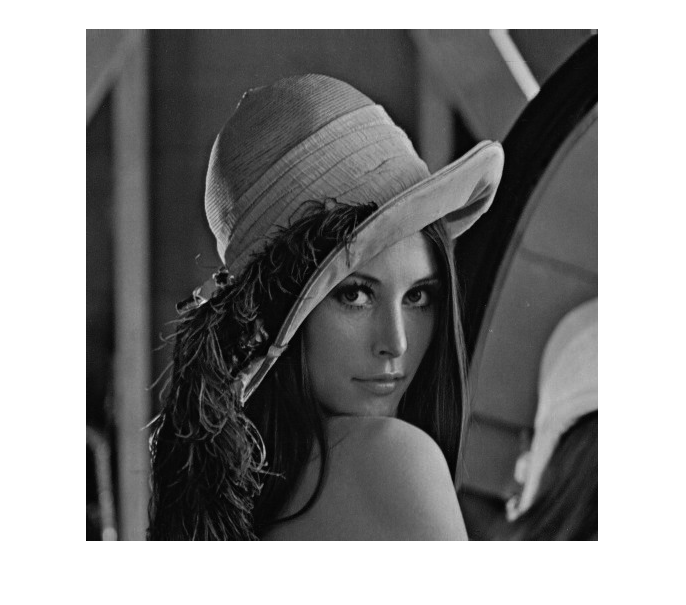

imshow(lena)

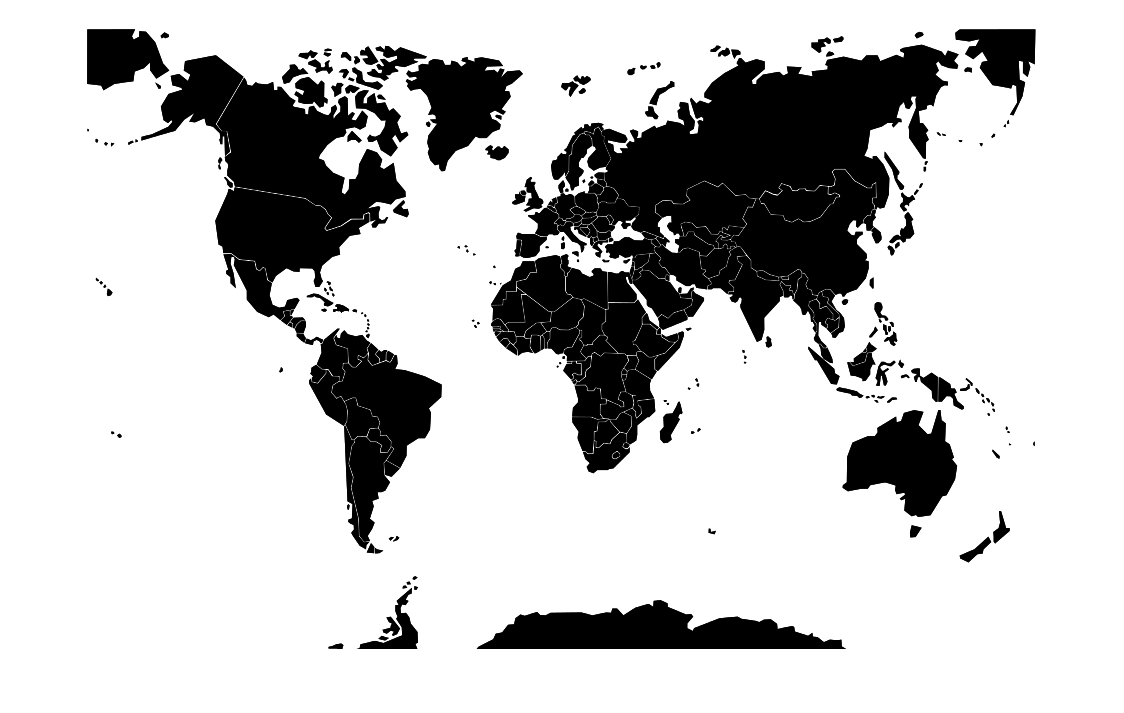

imshow(monde)

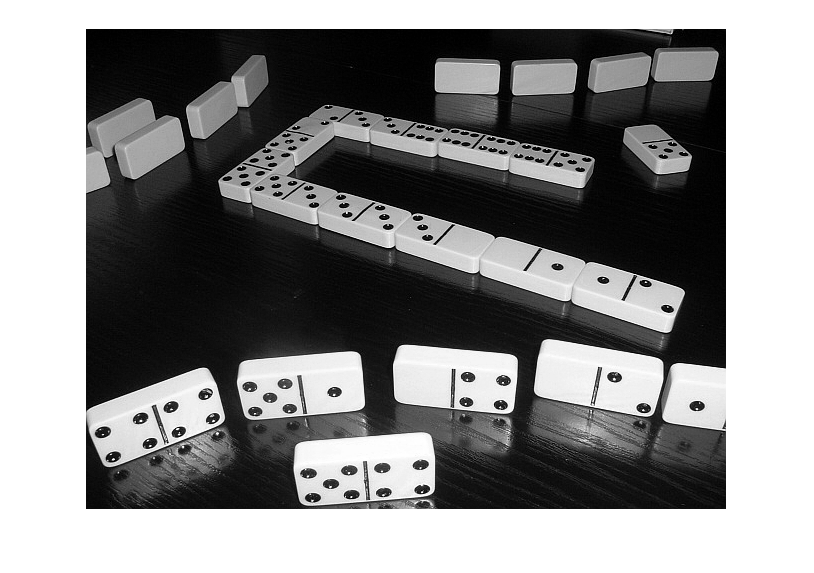

imshow(dominos)

## Filtres passe haut

h3 = [[-1 -1 -1];[0 0 0];[1 1 1]]

h3 =     -1    -1    -1
     0     0     0
     1     1     1


h4 = [[-1 -2 -1];[0 0 0];[1 2 1]]

h4 =     -1    -2    -1
     0     0     0
     1     2     1


h5 = [[0 1 0];[1 -4 1];[0 1 0]]

h5 =      0     1     0
     1    -4     1
     0     1     0


help conv2

 conv2 Two dimensional convolution.
    C = conv2(A, B) performs the 2-D convolution of matrices A and B.
    If [ma,na] = size(A), [mb,nb] = size(B), and [mc,nc] = size(C), then
    mc = max([ma+mb-1,ma,mb]) and nc = max([na+nb-1,na,nb]).
 
    C = conv2(H1, H2, A) first convolves each column of A with the vector
    H1 and then convolves each row of the result with the vector H2.  If
    n1 = length(H1), n2 = length(H2), and [mc,nc] = size(C) then
    mc = max([ma+n1-1,ma,n1]) and nc = max([na+n2-1,na,n2]).
    conv2(H1, H2, A) is equivalent to conv2(H1(:)*H2(:).', A) up to
    round-off.
 
    C = conv2(..., SHAPE) returns a subsection of the 2-D
    convolution with size specified by SHAPE:
      'full'  - (default) returns the full 2-D convolution,
      'same'  - returns the central part of the convolution
                that is the same size as A.
      'valid' - returns only t

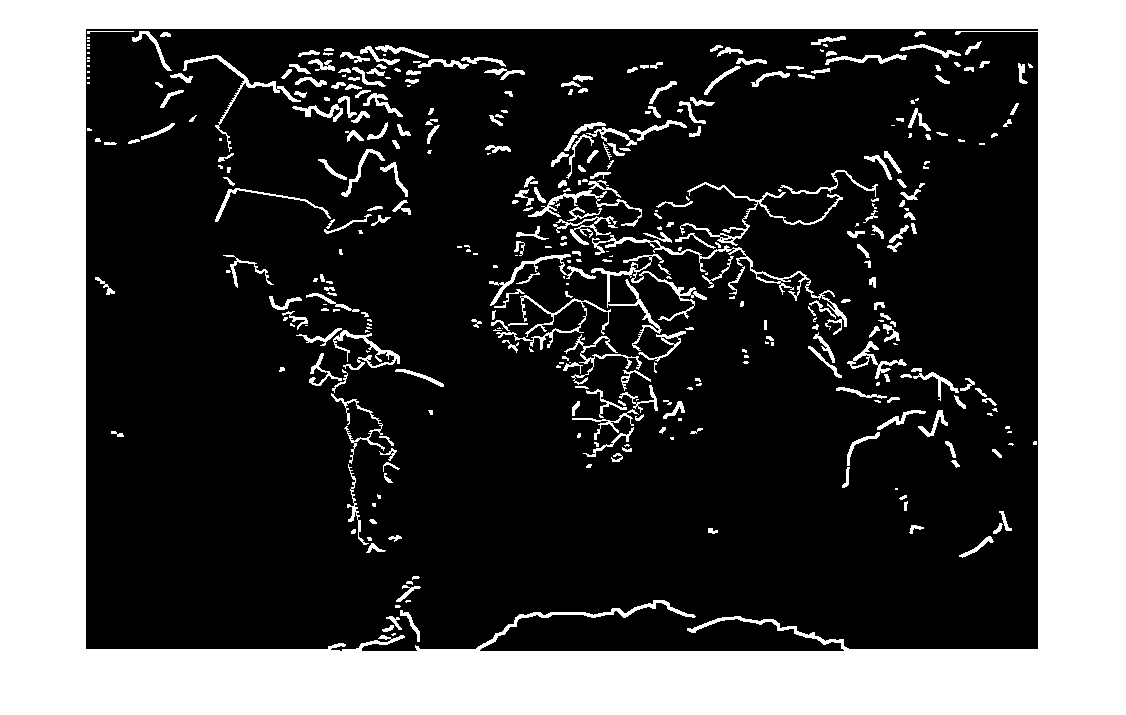

convol(monde, h3, false)

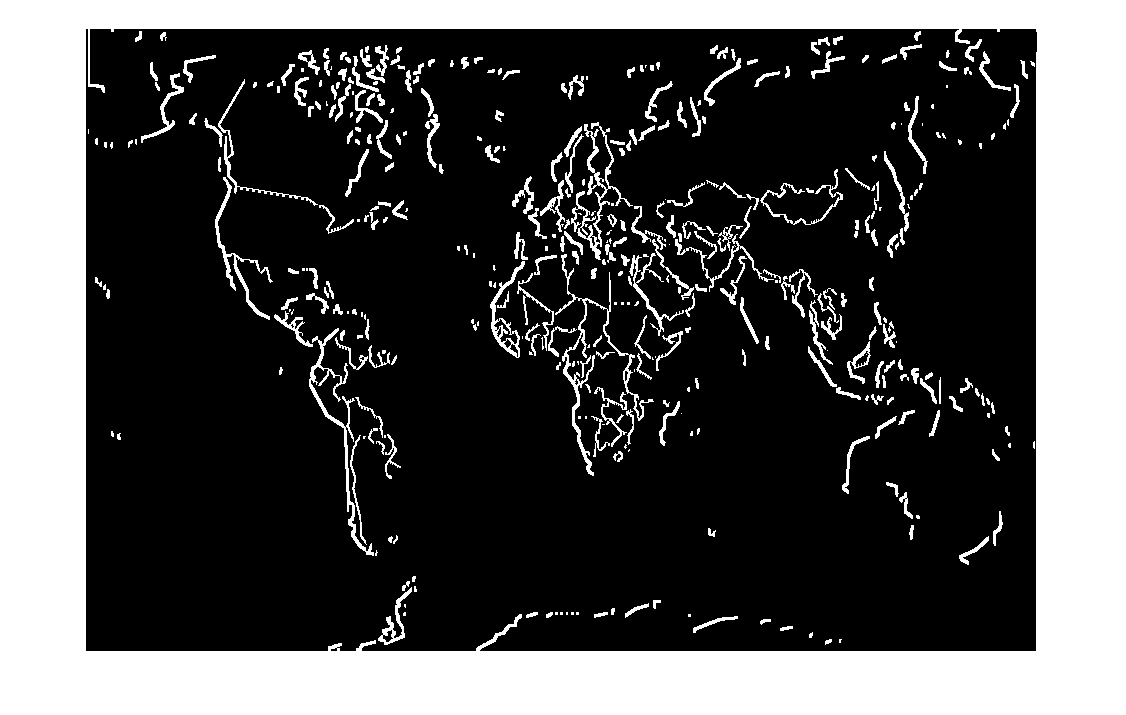

convol(monde, h3', false)

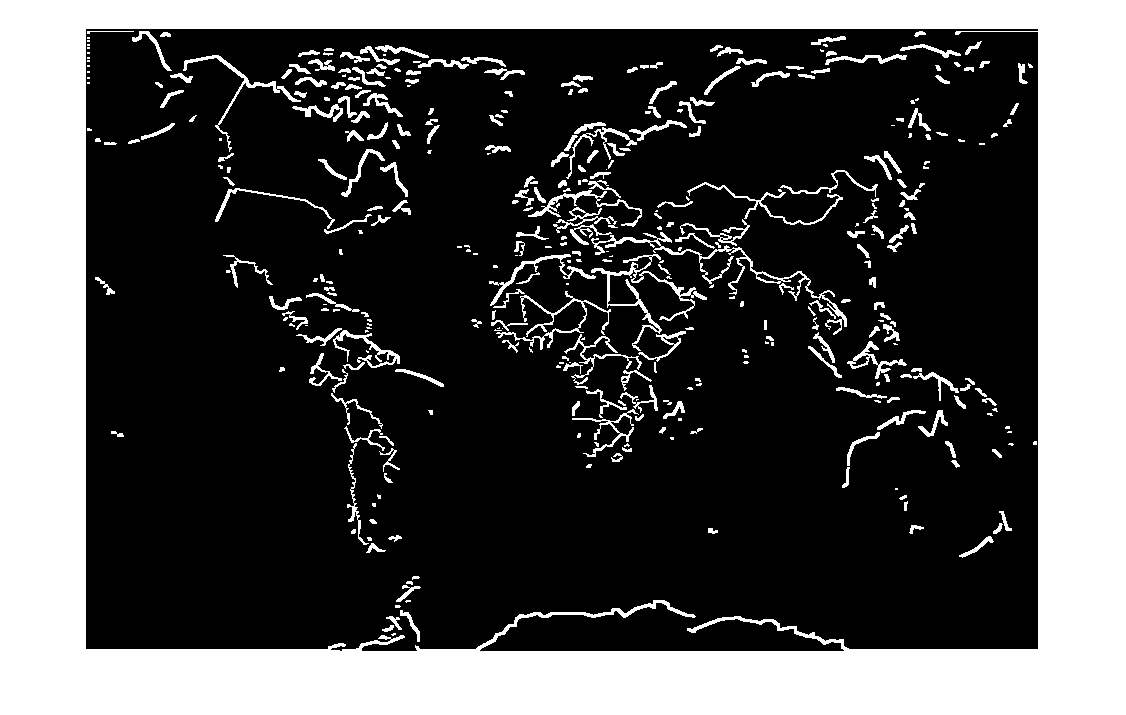

convol(monde, h4, false)

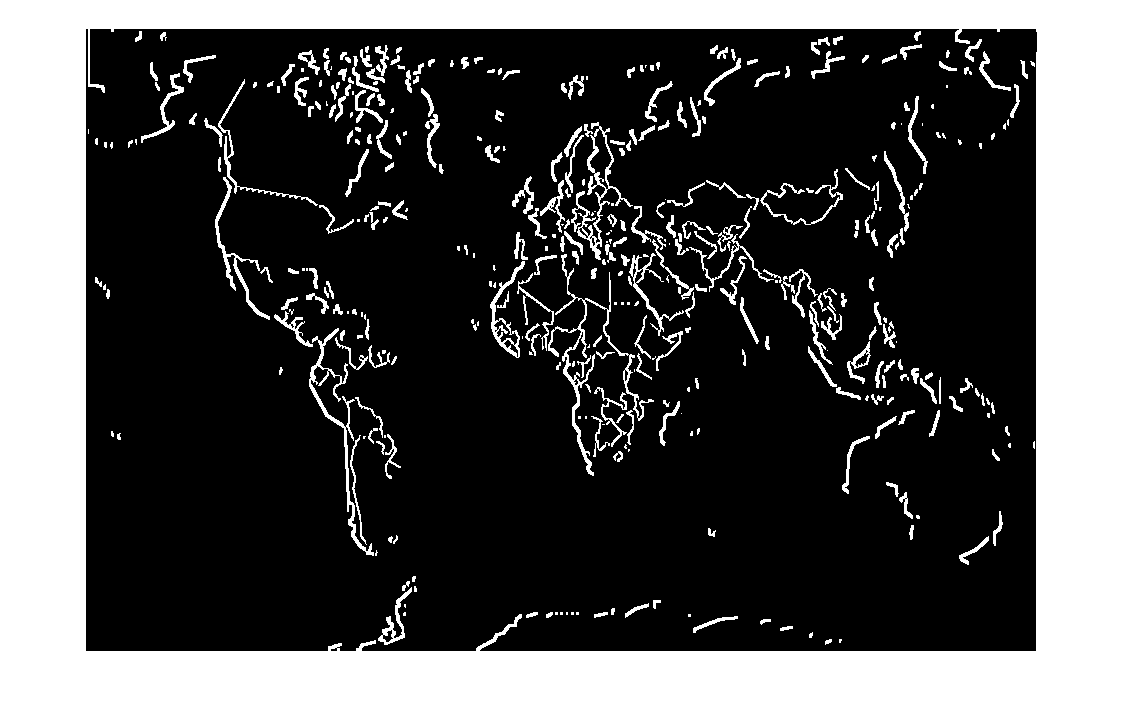

convol(monde, h4', false)

Le fait d'appliquer une seule fois les filtres h3 ou h4 sur l'image ne permettent de détecter qu'une partie des contours présents dans l'image.

h3_d = [[0 1 2];[-1 0 1];[-2 -1 0]]

h3_d =      0     1     2
    -1     0     1
    -2    -1     0


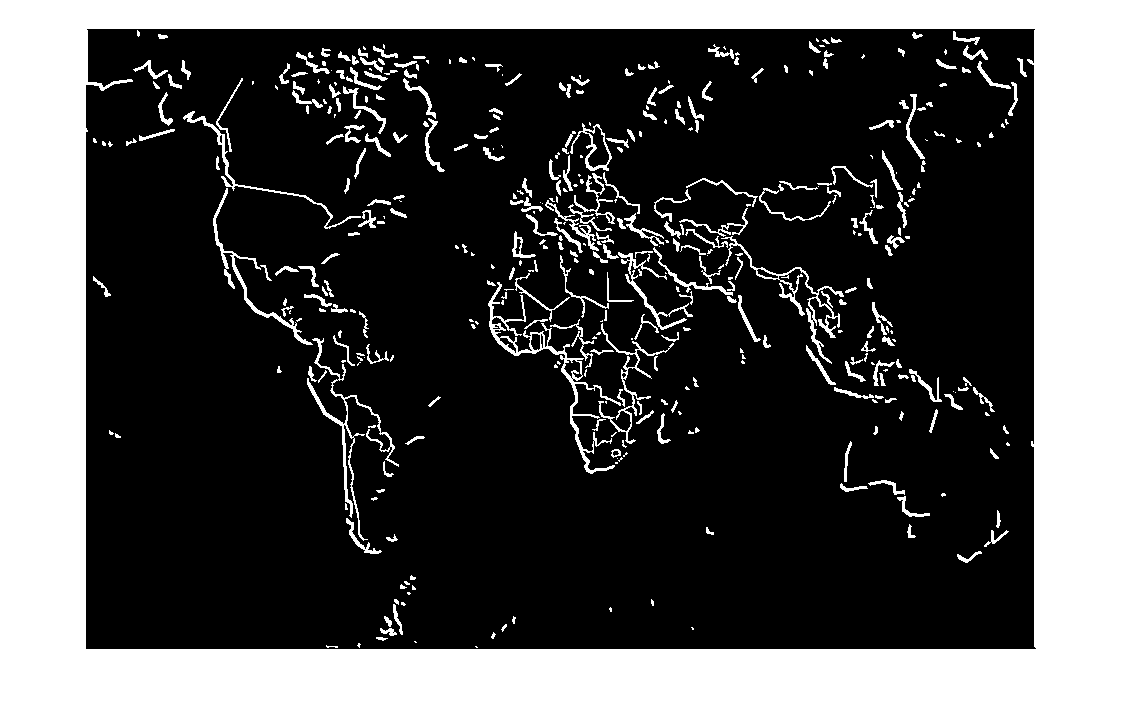

convol(monde, h3_d, false)

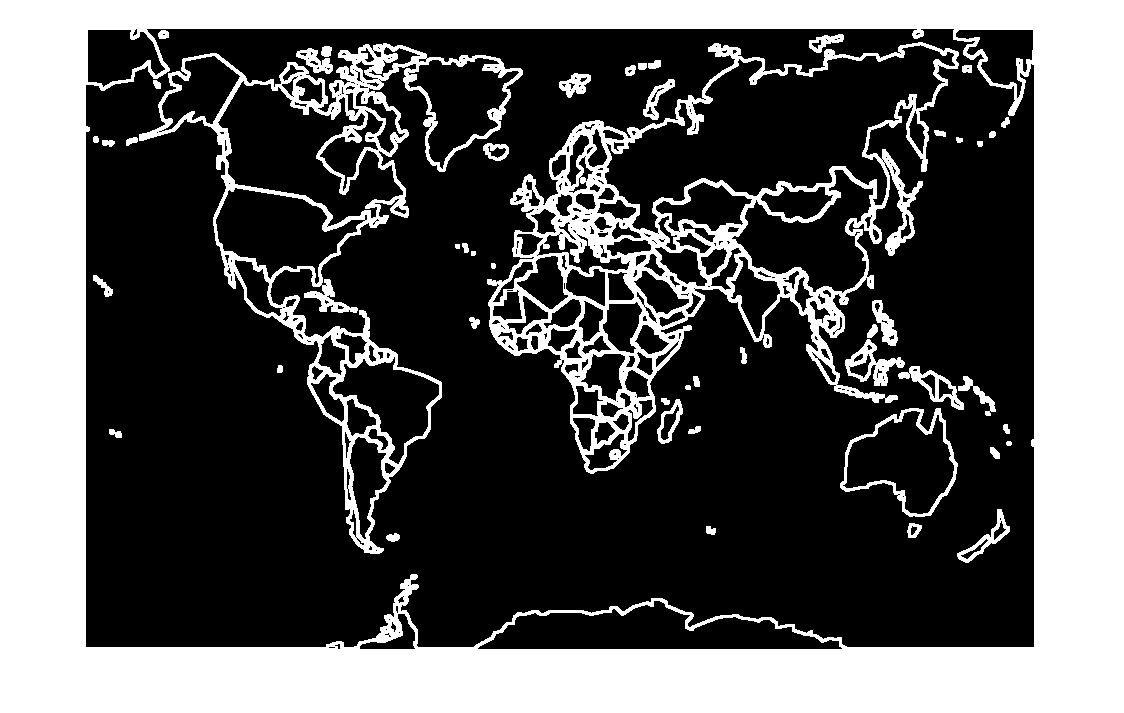

convol(monde, h3, true)

convol(monde, h4, true)

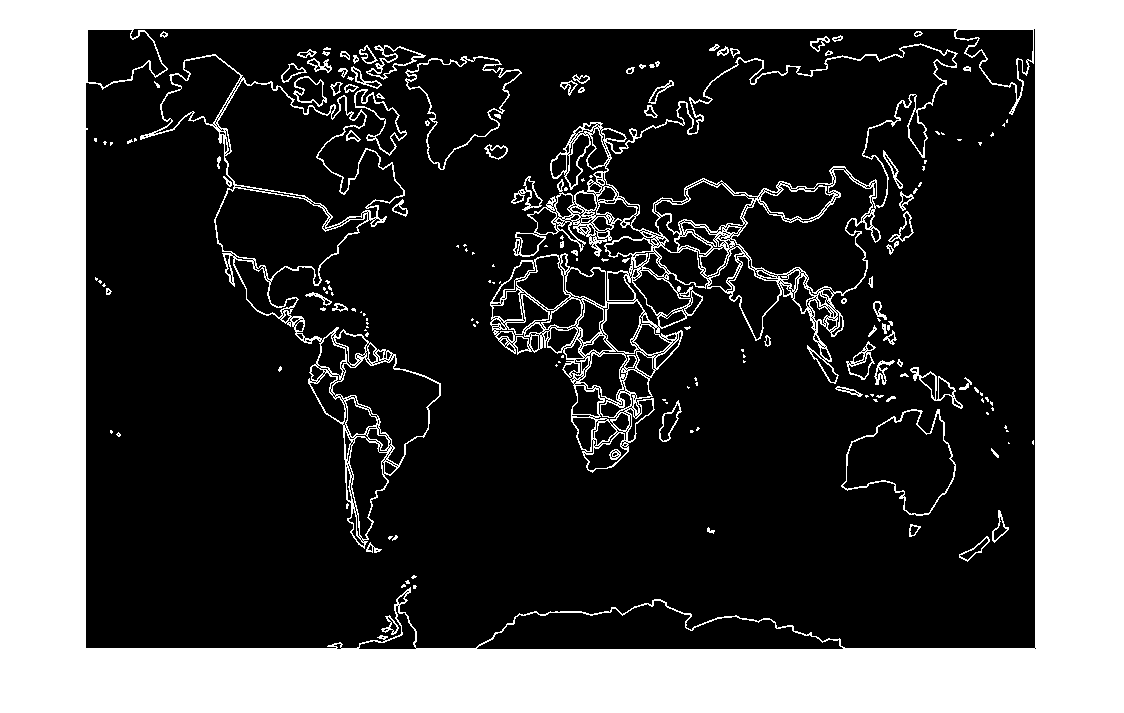

convol(monde, h5, false)

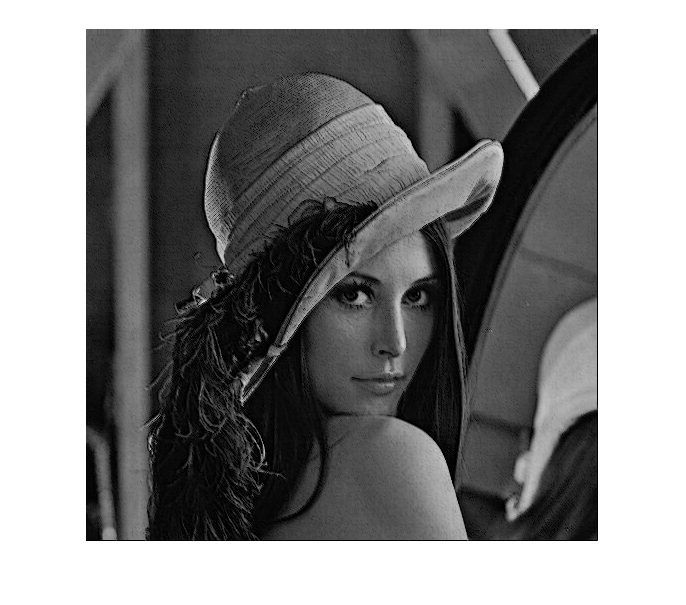

image = lena;
contraste = image - uint8(convol_in(image, h5, false));
imshow(contraste)

imshow(image)

## Filtres passe bas

h1 = (1/9) * [[1 1 1];[1 1 1];[1 1 1]]

h1 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


h2 = (1/16) * [[1 2 1];[2 4 2];[1 2 1]]

h2 =     0.0625    0.1250    0.0625
    0.1250    0.2500    0.1250
    0.0625    0.1250    0.0625


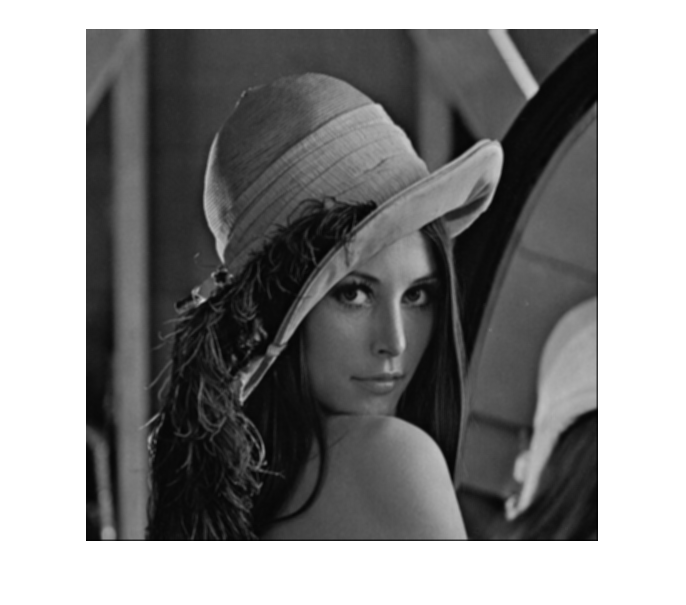

convol(lena, h1, false)

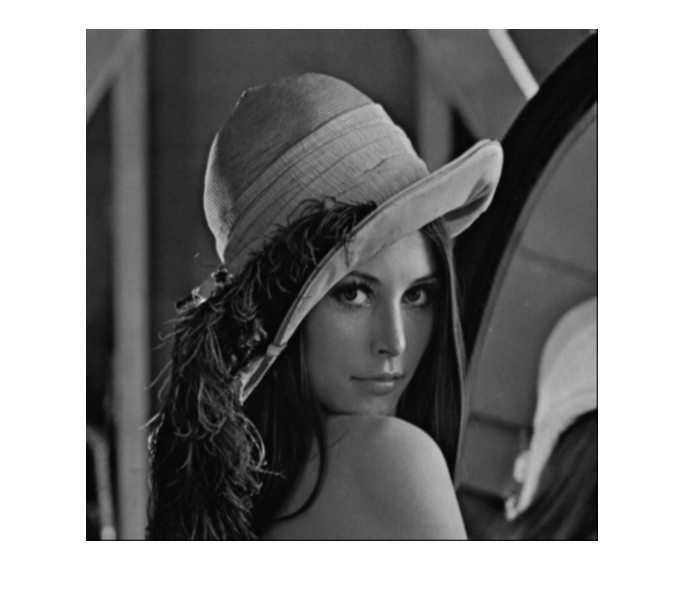

convol(lena, h2, false)

% Différences with TP1

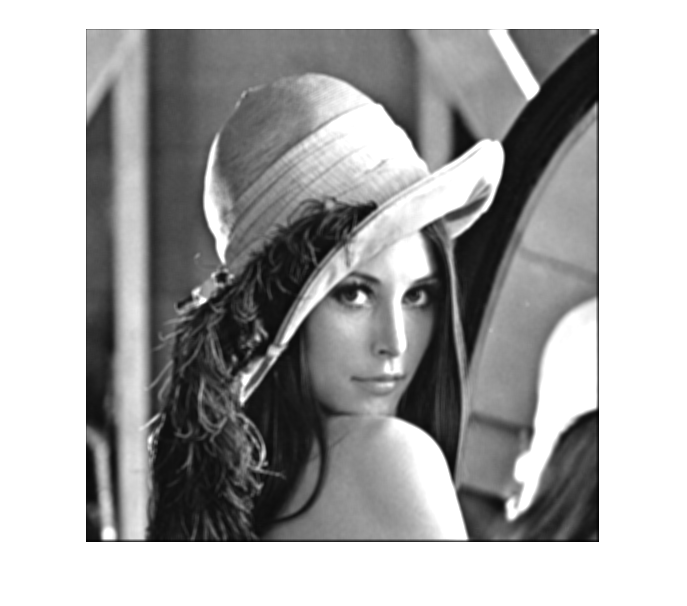

convol(lena, expand_mask(h1, 1), false)

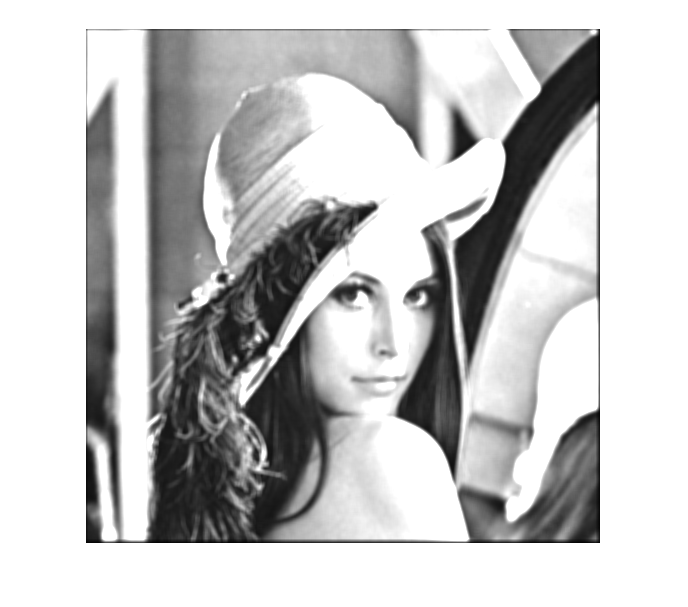

convol(lena, expand_mask(h1, 2), false)

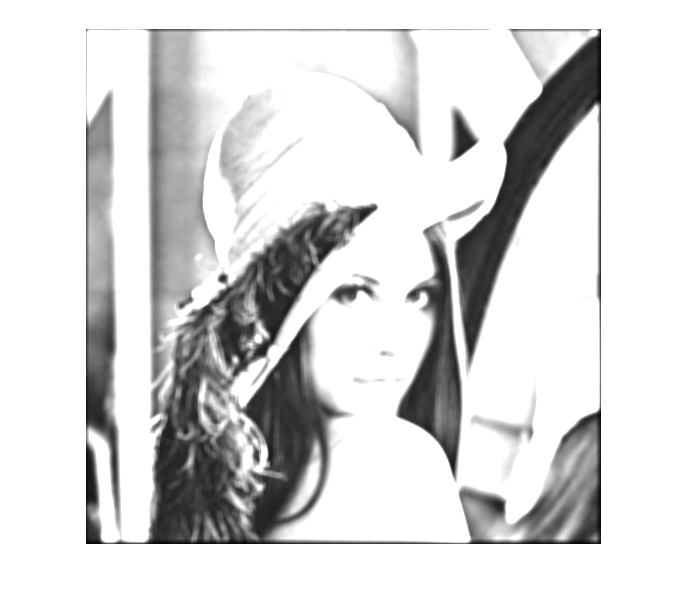

convol(lena, expand_mask(h1, 3), false)

Le fait d'augmenter la taille du filtre H1 éclaircit énormément l'image.

## Fonctions utilitaires

function img = convol_in(img, filtre, with_transpo)
    convol1 = conv2(filtre, img);
    if(with_transpo)
        convol2 = conv2(filtre', img);
        img = sqrt(power(convol1, 2) + power(convol2, 2));
    else
        img = convol1;
    end
    img(1:2,:) = [];
    img(:,1:2) = [];
    img = uint8(img);
end

function convol(img, filtre, with_transpo)
    a = convol_in(img, filtre, with_transpo);
    imshow(a)
end

function mask = expand_mask(mask, expansion)
    val = mask(1,1);
    mask = val * ones(size(mask) + expansion);
end